% 本脚本的目的寻找正确的矫正值
% tried by Gao at 20171102
% % 2D  100
% % 4D  200
% % 6D  300
% % 7D  350
% % 8D  400

# **这是我随便插入的文本！**

# 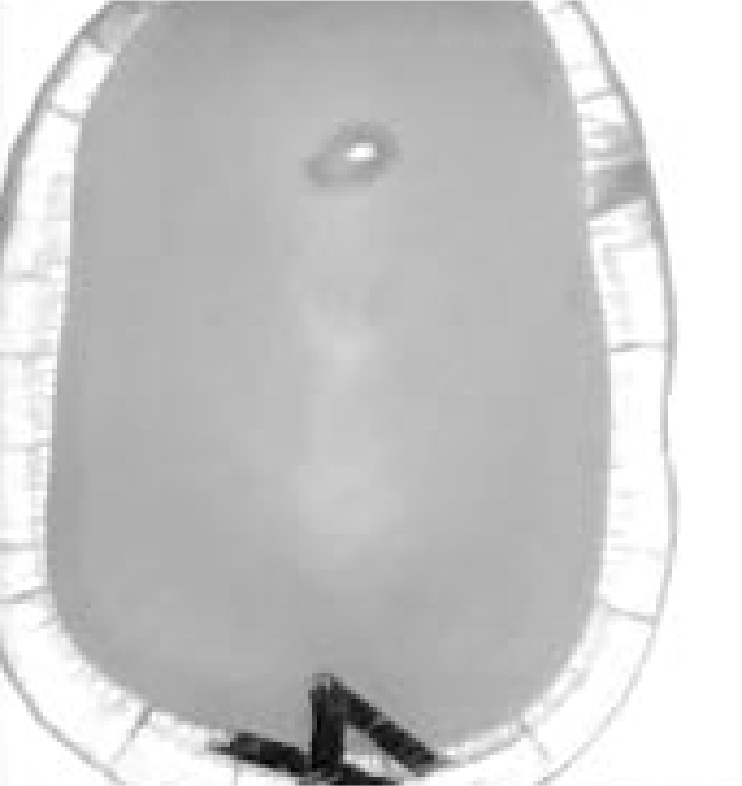

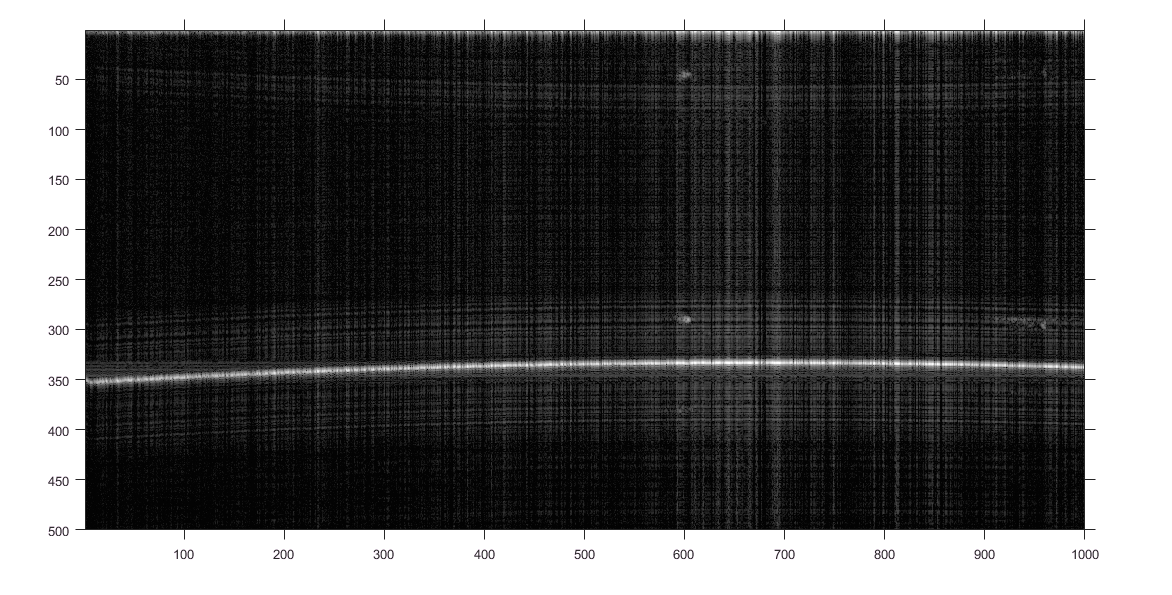


clear; close all; clc;
path_name = 'D:\OCT_Sync\Data\OCT-Data\Data_3D\Data_20171102\L45_1';  %%% 设置数据路径
addpath(path_name);                             % 添加数据文件%%%%%% correct value
I = imread('1.bmp');                            %%% I为为参考帧
imshow(I);axis on;


cor = 10;
% [I] = img_cor(I,1);                           %%% 图像校正

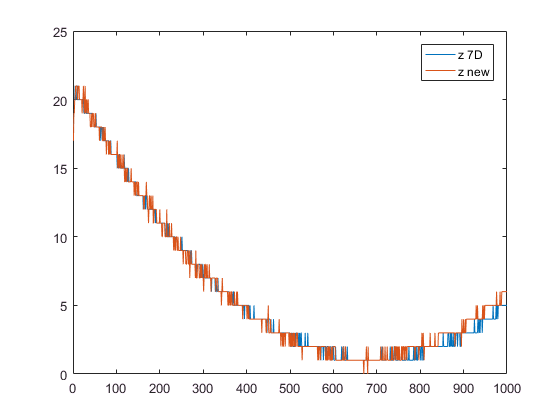

for i = 1:1000
    line = I(cor:500,i);                        % 对反射板线加平滑
    [~,surface(1,i)] = max(line);
end

surface_pro = surface + (cor-1)*ones(1,1000);   % get the position of surface
min_val = min(surface_pro);
z_new = surface_pro - min_val*ones(1,1000);     % be attention to modificating the name in saving
z_correct = z_new;
save correct_7D_20171102_xx z_correct           %%%


load('correct_7D');        
z_7D = z_correct;
figure,
x = 1:1000;
plot(x,z_7D,x,z_new);       
legend('z 7D','z new','Location','Northeast');             %%%

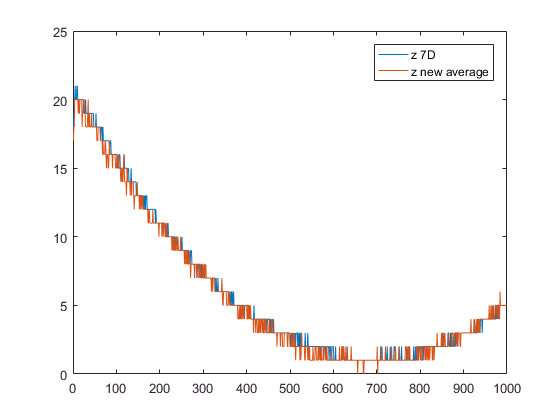

%%%%%%%%%%%%%%%%% use for paper,creat a calibration profile line  %%%%%%%%%%%%%%%
% coronal_int = 7.2/1000;        % mm unit,interval
% figure,
% plot(x*coronal_int,z_7D);
% xlabel('Distance of X axis  [mm]','FontSize',18);
% ylabel('Pixel Numbel of Calibration','FontSize',18);
% set(gca,'FontSize',14,'XTick',0:2:8,'YTick',0:5:25);   
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
load('correct_7D_20171102_z1');             %%
z1 = z_correct;
load('correct_7D_20171102_z2');             %%
z2 = z_correct;
load('correct_7D_20171102_z3');             %%
z3 = z_correct;
load('correct_7D_20171102_z4');             %%
z4 = z_correct;
load('correct_7D_20171102_z5');             %%
z5 = z_correct;
z_correct = (z1+z2+z3+z4+z5)/5;
z_correct = round(z_correct);
figure,
x = 1:1000;
plot(x,z_7D,x,z_correct);         %%%
legend('z 7D','z new average','Location','Northeast'); 

save correct_7D_2017xx z_correct              %% rename!!!